# ARX model

## initialization

clear all; close all
t_step=0.1;
t=0:t_step:50;
T=7;
a=0.8;b=1;


## Input Data Generation

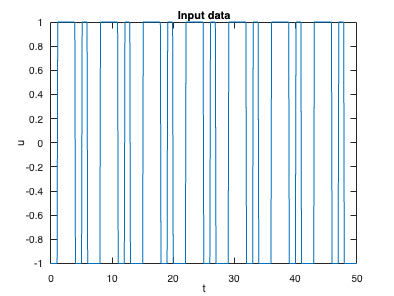

for i = 1: length(t)
    if (mod(t(i),T) >1 && mod(t(i),T) < 4)|| (mod(t(i),T) < 6 && mod(t(i),T)> 5)
        u(i,1)=1;
    else  
        u(i,1)= -1;
    end
e= randn(length(t),1)*sqrt(0.1);
end

figure(1)
plot(t,u)
xlabel('t'); ylabel('u')
title('Input data');

## Output Data Generation

or 

where 

A=[1 -a];
B=[0 b];
C=1;

Sys  = idpoly(A,B,C,1,1,0.1); 
y=sim(Sys,[u e]);

## ARX Model Using MATLAB Embedded Function

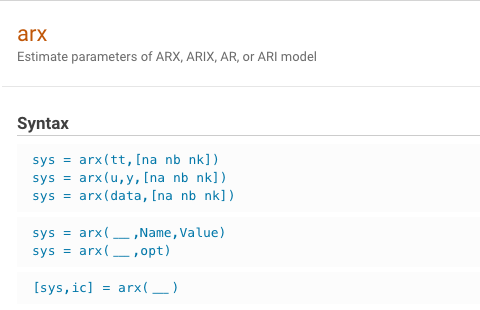

Z=[y,u];
na=2; % Autoregressive model order 
nb=1; % Exogeneous input order 
nk=1; % input-output delay
theta_ls=arx(Z,[na nb nk],'Ts',t_step)    % arx function used

theta_ls =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.7977 z^-1 - 0.002122 z^-2           
                                                   
  B(z) = 1.003 z^-1                                
                                                   
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=1   nk=1
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "Z".     
Fit to estimation data: 97.41% (prediction focus)
FPE: 0.009302, MSE: 0.009118                     
 
Model Properties


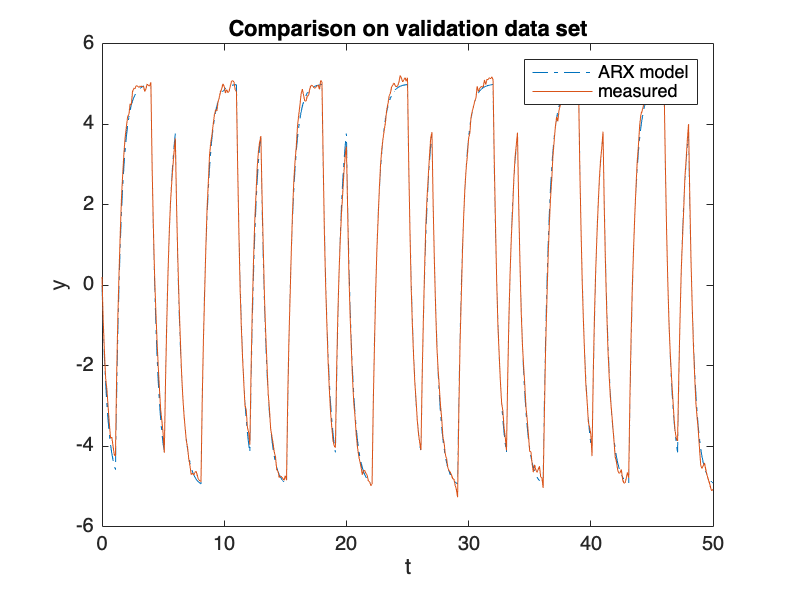

Data=iddata(y,u);           % iddata function for data formatting 
yhat=lsim(theta_ls, u);     % lsim function for estimated output 

plot(t,yhat,'-.',t,y);
legend('ARX model','measured')
xlabel('t'); ylabel('y')
title('Comparison on validation data set');
hold on

## PEM Model (For ARMAX)

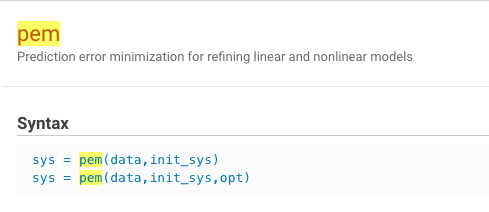


na = 2; nb = 2; nc = 2;
theta_pem = armax(Data,[na nb nc 1]); % ARMAX using PEM
yhat2=lsim(theta_ls, u);     % lsim function for estimated output 
plot(t,yhat2,'--')